# DSP Pipeline Analysis

Program to plot the outputs from the local processing on the SHARC Buoy. 

%Specify location of file
outdir_2 = "C:\Users\uctsh\Documents\MATLAB";

%Specify variables
opts = delimitedTextImportOptions("NumVariables", 1);
opts.VariableNames = ["Heave"];
opts.VariableTypes = ["double"];

%Read in table
wavefile = fullfile(outdir_2, "SHARC_raw.txt");
WaveTable = readtable(wavefile, opts);

## Plot raw acceleration data

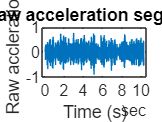

Fs = 100;
WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);
plot(WaveTimeTable.Time, WaveTimeTable.Heave);
xlabel("Time (s)");
ylabel("Raw accleration");
title("Raw acceleration segment");

## Plot scaled data

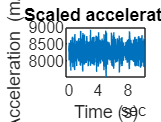

Fs = 100;
WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);
plot(WaveTimeTable.Time, WaveTimeTable.Heave);
xlabel("Time (s)");
ylabel("Acceleration (m/s^2)");
title("Scaled acceleration");

##  Plot detrended data

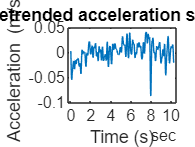

Fs = 100;
WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);
plot(WaveTimeTable.Time, lowpass(WaveTimeTable.Heave, 2, Fs));
xlabel("Time (s)");
ylabel("Acceleration (m/s^2)");
title("Detrended acceleration segment");

##  Plot LPF + Decimated data

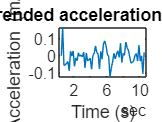

Fs = 6.25;
WaveTimeTable = table2timetable(WaveTable, 'SampleRate', Fs);
plot(WaveTimeTable.Time, WaveTimeTable.Heave);
xlabel("Time (s)");
ylabel("Acceleration (m/s^2)");
title("Detrended acceleration segment");